# **Spline - Definitie generala:**

#### Definitia formala:

    Un **spline** este o functie compusa din **mai multe polinoame**, definite pe subintervale adiacente, care sunt **legate intre ele intr-un mod neted**, adica astfel incat funcia si anumite derivate ale ei (de obicei pana la ordinul 2) sunt **continue** la punctele de legatura 

#### Mai intuitiv:

    Un spline este ca **o curba flexibila care leaga puncte** (noduri) prin bucati de polinoame astfel incat tranzitia intre bucati este lina: fara "colturi" sau salturi

    Fie un interval [a,b][a,b][a,b] impartit in subintervale de forma [x1,x2],[x2,x3],...[xn-1,xn] , spline-ul de grad k este o funcție:

$S\left(x\right)=\left\lbrace \begin{array}{ll}
P_1 \left(x\right) & x\in \left\lbrack x_1 ,x_2 \right\rbrack \\
P_{n-1} \left(x\right) & x\in \left\lbrack x_{n-1} ,x_n \right\rbrack 
\end{array}\right.$... si cazurile intermediare (nu stiu sa le afisez)

unde fiecarePi(x) este un **polinom de grad ≤ k**, si:

- S(x) este **continua pe tot intervalul** [a,b],

- Derivatele pana la ordinul k−1 sunt **continue la noduri** (xi).

# **Spline cubic natural**

    Un Spline cubic in care **nu se impune niciun comportament anume la capete**, ci se presupune ca **curbura este zero**, in extremitati. Astfel inseamna ca spline-ul presupune ca curbura este zero in expremitati.

**Caracteristici:**

- Conditii de margine s′′(x1)=0,s′′(xn)=0

- Sistemul de ecuatii care trebuie rezolvat este **tridiagonal** - usor de calculat

**Avantaje:**

- Cea ma isimpla si stabila forma spline

- Foarte potrivita daca nu ai infromatii despre derivate

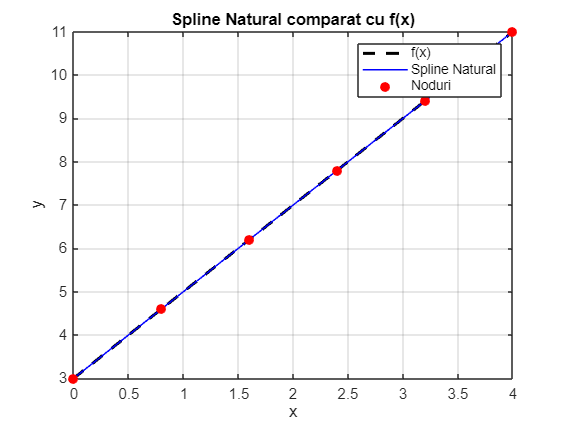

f = @(x) 2*x + 3;              % functia f(x)
a = 0; b = 4;                  % capetele intervalului
n_noduri = 6;                  % cate noduri vrem
n_eval = 400;                  % cate puncte vrem sa evaluam spline-ul

x_noduri = linspace(a, b, n_noduri);     % noduri pentru interpolare
x_eval = linspace(a, b, n_eval);         % puncte de evaluare

[yy_spline, spline_sym, eroare] = SplineNatural(f, x_noduri, x_eval);

figure;
plot(x_eval, f(x_eval), 'k--', 'LineWidth', 2); hold on;
plot(x_eval, yy_spline, 'b-', 'LineWidth', 1);
plot(x_noduri, f(x_noduri), 'ro', 'MarkerFaceColor', 'r');
legend('f(x)', 'Spline Natural', 'Noduri');
title('Spline Natural comparat cu f(x)');
xlabel('x'); ylabel('y');
grid on;


% disp('Polinoamele spline-ului pe intervale:');
% for i = 1:length(spline_sym)
%     fprintf('Interval [%f, %f]:\n', x_noduri(i), x_noduri(i+1));
%     disp(spline_sym{i});
% end

fprintf('Eroare maxima de aproximare: %.2e\n', eroare);

Eroare maxima de aproximare: 1.78e-15


# **Spline complet**

**Ce este?**

    Spline-ul complet este un tip de interpolare spline cubica in care se cunosc si se impun valorile derivatei prime in capetele interalului. Adica, pe langa faptul ca spline-ul trece prin punctele date, se asigura si ca panta este corecta la inceput si sfarsit

**Caracteristici:**

- Impune: s′(x1)=f′(x1), s'(xn) = f'(xn)

- Restul derivatelor sunt determinate automat din conditiile de netezime si continuitate

**Avantaje:**

- Control precis al comportamentului la margini (ideal daca ai informatii despre panta in capete)

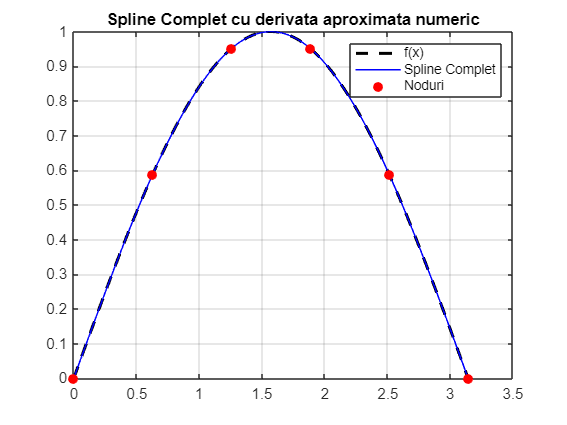

f = @(x) sin(x);                   % functia 
a = 0; b = pi;                     % interval
n = 6;                             % numar de noduri
x_noduri = linspace(a, b, n);     
x_eval = linspace(a, b, 400);

[yy, polinoame, eroare] = SplineComplet(f, x_noduri, x_eval);  % nu mai dam df

% Grafic
figure;
plot(x_eval, f(x_eval), 'k--', 'LineWidth', 2); hold on;
plot(x_eval, yy, 'b-', 'LineWidth', 1);
plot(x_noduri, f(x_noduri), 'ro', 'MarkerFaceColor', 'r');
legend('f(x)', 'Spline Complet', 'Noduri');
title('Spline Complet cu derivata aproximata numeric');
grid on;


% Afisare formule spline
% disp('Polinoamele spline-ului pe intervale:');
% for i = 1:length(polinoame)
%     fprintf('Interval [%f, %f]:\n', x_noduri(i), x_noduri(i+1));
%     disp(polinoame{i});
% end

fprintf('Eroare maxima de aproximare: %.2e\n', eroare);

Eroare maxima de aproximare: 4.34e-04


# **Spline cubic cu derivate de ordinul al doilea**

    Este un spline cubic unde, in loc sa se impuna derivata **prima** la capete, se impune **derivata a doua**. Astfel controleaza **curbura** spline-ului in margini. 

**Caz particular:**

- Daca s′′(x1)=s′′(xn)=0, atunci devine spline-ul **natural**

**Caracterisciti:**

- Poti impune, de exemplu s′′(x1)=a , s′′(xn)=b

- Util daca vrei o curba care incepe si se termina cu o anumita forma de "rotunjire"

f = @(x) x.^3 + 2*x.^2 - x + 5;   % functie perfect derivabila
a = 1;
b = 2;
n = 6;

x_noduri = linspace(a, b, n);
x_eval = linspace(a, b, 400);

[yy, polinoame, eroare] = SplineCubicDeriv2(f, x_noduri, x_eval);

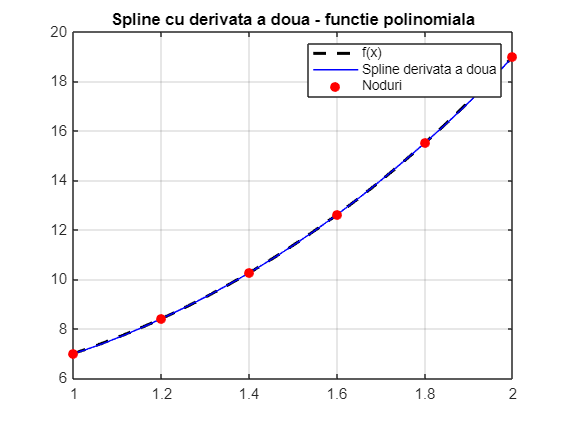


% Afisare grafica
figure;
plot(x_eval, f(x_eval), 'k--', 'LineWidth', 2); hold on;
plot(x_eval, yy, 'b-', 'LineWidth', 1);
plot(x_noduri, f(x_noduri), 'ro', 'MarkerFaceColor', 'r');
legend('f(x)', 'Spline derivata a doua', 'Noduri');
title('Spline cu derivata a doua - functie polinomiala');
grid on;


% Afisare eroare
fprintf('Eroare maxima: %.2e\n', eroare);

Eroare maxima: 3.15e-02


# **Spline Periodic**

    Spline-ul periodic este unul care **incepe si se termina in acelasi punct**, avand si **aceeasi panta si curba la inceputul si sfarsit**. Este potrivit pentru functii ciclice

**Conditii:**


$$\begin{array}{l}
f\left(x_1 \right)=f\left(x_n \right)\\
f^{\prime } \left(x_1 \right)=f^{\prime } \left(x_n \right)\\
{f^{\prime } }^{\prime } \left(x_1 \right)={f^{\prime } }^{\prime } \left(x_n \right)
\end{array}$$


**Caracteristici:**

- Impune conditii de periodicitate la capete

- Necesita adaptarea sistemului de ecuatii pentru a inchide bucla

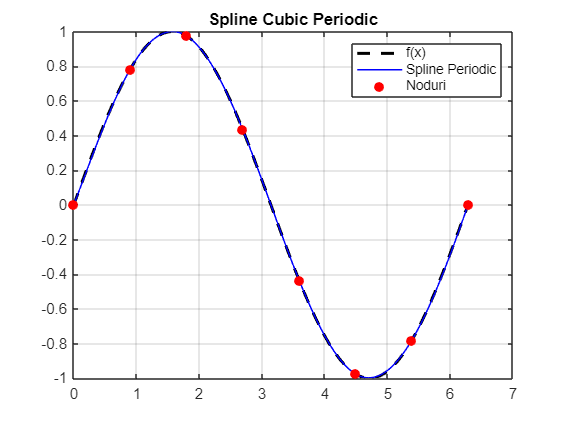

f = @(x) sin(x);           % functie periodica
a = 0; 
b = 2*pi;                  % domeniu periodic
n = 8;                     % numar noduri
x_noduri = linspace(a, b, n);
x_eval = linspace(a, b, 400);

[yy, polinoame, eroare] = SplinePeriodic(f, x_noduri, x_eval);

figure;
plot(x_eval, f(x_eval), 'k--', 'LineWidth', 2); hold on;
plot(x_eval, yy, 'b-', 'LineWidth', 1);
plot(x_noduri, f(x_noduri), 'ro', 'MarkerFaceColor', 'r');
legend('f(x)', 'Spline Periodic', 'Noduri');
title('Spline Cubic Periodic');
grid on;


% disp('Polinoamele spline-ului pe intervale:');
% for i = 1:length(polinoame)
%     fprintf('Interval [%f, %f]:\n', x_noduri(i), x_noduri(i+1));
%     disp(polinoame{i});
% end
fprintf('Eroare maxima: %.2e\n', eroare);

Eroare maxima: 7.92e-03


# **Spline de Boor (B-spline)**

    Spre deosebire de spline-urile care **interpoleaza** punctele (adica trec exact prin ele), spline-ul Boor foloseste** functii de baza (B-spline)** pentru a contrui o curba care **aproximeaza** punctele si este extrem de **neteda si stabila numeric.**

**Caracteristici:**

- Control local: modificarea unui punct de control afecteaza doar o parte a curbei

- Nu trece prin toate punctele (decat daca e formulat special sa o faca)

- Reprezentare parametrica

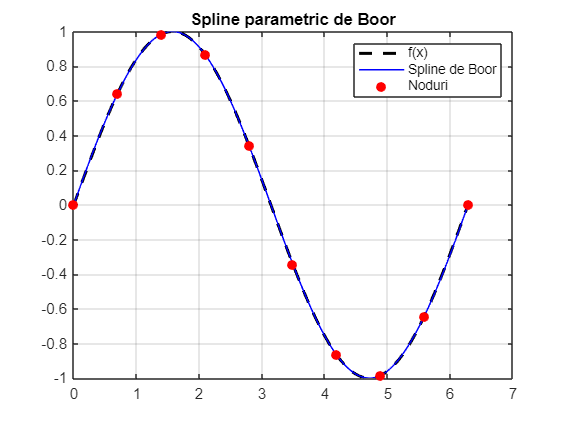

f = @(x) sin(x);           % functie de interpolat
a = 0; b = 2*pi;           % domeniu
n_noduri = 10;
n_eval = 400;

[xx, yy, pp_x, pp_y, eroare] = SplineDeBoor(f, a, b, n_noduri, n_eval);

% Grafic
figure;
plot(xx, f(xx), 'k--', 'LineWidth', 2); hold on;
plot(xx, yy, 'b-', 'LineWidth', 1);
plot(linspace(a, b, n_noduri), f(linspace(a, b, n_noduri)), 'ro', 'MarkerFaceColor', 'r');
legend('f(x)', 'Spline de Boor', 'Noduri');
title('Spline parametric de Boor');
grid on;


fprintf('Eroare maxima spline de Boor: %.2e\n', eroare);

Eroare maxima spline de Boor: 4.41e-03


# **Spline Hermite cubic C^1**

**Ce este?**

    Spline Hermite cubic este un spline care i**nterpoleaza atat valorile functiei**, cat si **derivata** prima in fiecare nod

**Conditii:**


$$s\left(x_i \right)=f\left(x_i \right),s^{\prime } \left(x_i \right)=f^{\prime } \left(x_i \right),$$
 
$$\textrm{pentru}\;\textrm{fiecare}\;i,\;\textrm{unde}\;s\left(x\right)\;\textrm{este}\;\textrm{polinomul}\;\textrm{spline}\;\textrm{Hermite}$$


**Caracterisciti:**

- Fiecare segment este un polinom de grad 3, construit sa potriveasca atat valoarea, cat si derivata in capete

- Asigura o tranzitie neteda cu pante impuse

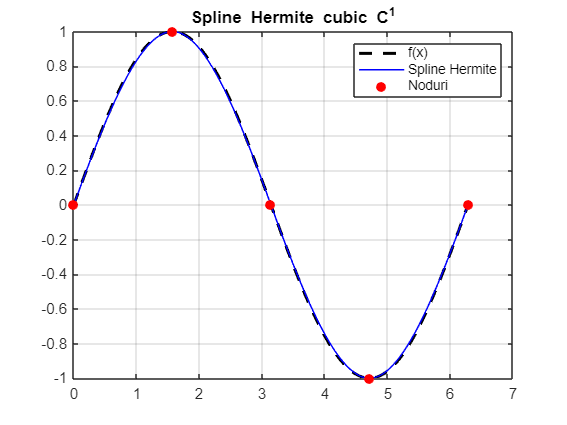

f = @(x) sin(x);          % Functia f(x)
df = @(x) cos(x);         % Derivata f'(x)

a = 0; 
b = 2*pi;
x_noduri = linspace(a, b, 5);      % noduri de interpolare
x_eval = linspace(a, b, 300);      % puncte de evaluare

[yy, p, err] = SplineHemite(f, df, x_noduri, x_eval);

% Grafic
figure;
plot(x_eval, f(x_eval), 'k--', 'LineWidth', 2); hold on;
plot(x_eval, yy, 'b-', 'LineWidth', 1);
plot(x_noduri, f(x_noduri), 'ro', 'MarkerFaceColor', 'r');
legend('f(x)', 'Spline Hermite', 'Noduri');
title('Spline Hermite cubic C^1');
grid on;